sensor_data = readtable('weight_cont_ini_14.12g.csv','Delimiter',',');
sensor_data(end,:) = [];

stamp_data = readmatrix('bigger_weight_with_time.txt');

time = sensor_data{:,1}./1000;
raw_data = sensor_data{:,2};

data2plot = [];

for i = 1:length(stamp_data(:,1))
    clip_ind_stt = find(time > stamp_data(i,1),1);
    clip_ind_stp = find(time > stamp_data(i,1)+10,1);

    data_clip = raw_data(clip_ind_stt:clip_ind_stp);

    mean_data = mean(data_clip);

    data2save = [stamp_data(i,2)+14.12,mean_data];

    data2plot = [data2plot; data2save];
end

p = polyfit(data2plot(:,1),data2plot(:,2),1)

p = 1.0e+07 *

   -0.0001    3.1311



y_fit = polyval(p,data2plot(:,1));

R = corrcoef(data2plot(:,2),y_fit);
R_sq = R.^2

R_sq =     1.0000    0.9992
    0.9992    1.0000


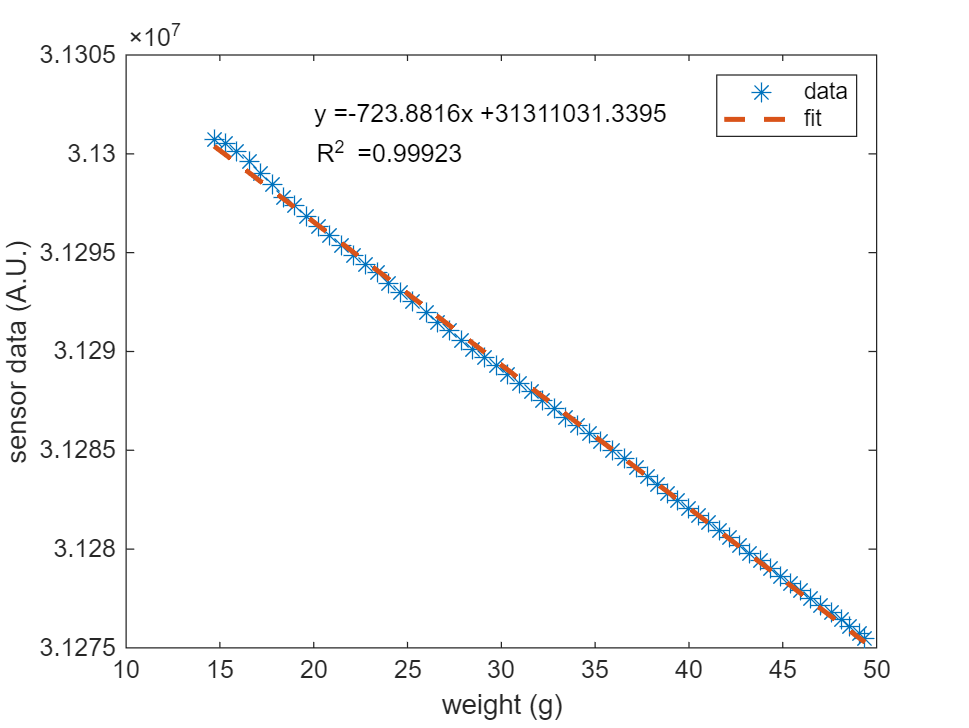


equation_txt = strcat('y = ',num2str(p(1)),'x + ',num2str(p(2)));
R_sq_txt = strcat('R^2 = ',num2str(R_sq(1,2)));

figure; 
plot(data2plot(:,1),data2plot(:,2),'*','MarkerSize',8)
hold on
plot(data2plot(:,1),y_fit,'--','LineWidth',2);
text(20, 3.1302*10^7, equation_txt);
text(20, 3.13*10^7, R_sq_txt);
hold off
legend('data','fit');
ylabel('sensor data (A.U.)');
xlabel('weight (g)');